# Demo: how to create basis functions?

This demo shows how to use the `createBasisFunctions` function to construct spline basis functions for use as fixed effects while fitting linear mixed-effects models

## Requirements

Please modify this paths to where you have downloaded the FEMA toolbox; if you already have FEMA on your MATLAB path, then this step is not required

addpath(genpath('/Applications/Projects/2025-11-28_FEMA-Demo/cmig_tools-main'))

## Simulate a distribution of age ranges

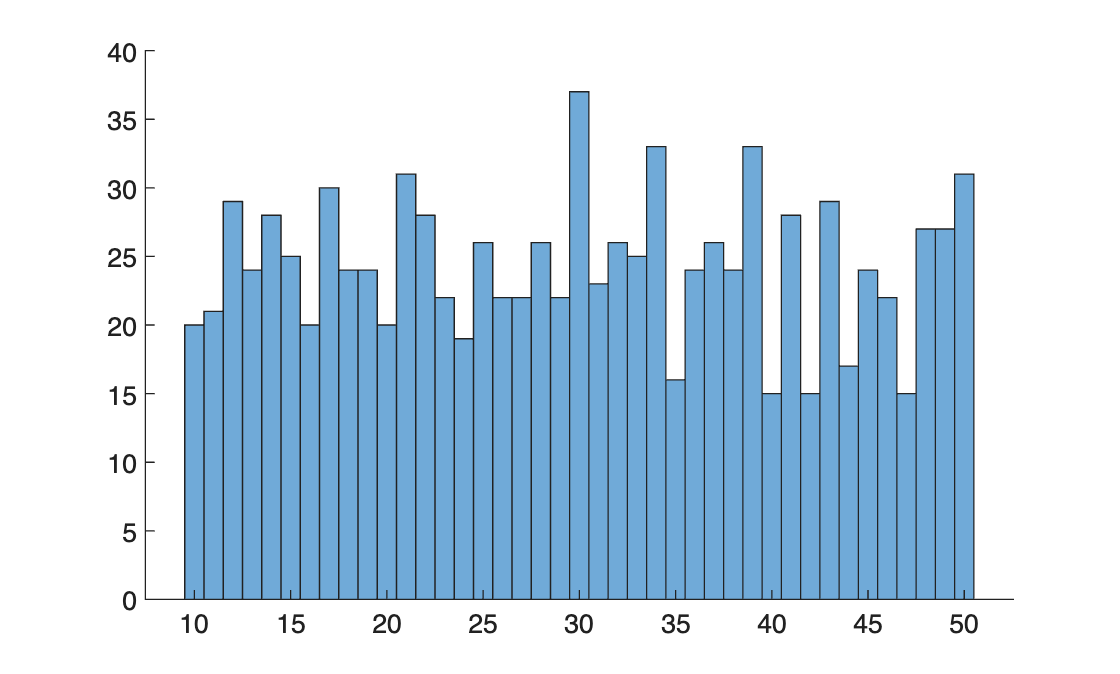

rng(100, 'twister');
age = sort(randi([10 50], 1000, 1));

figure;
histogram(age);
box off

## Version 1: create basis functions by placing knots at the percentiles

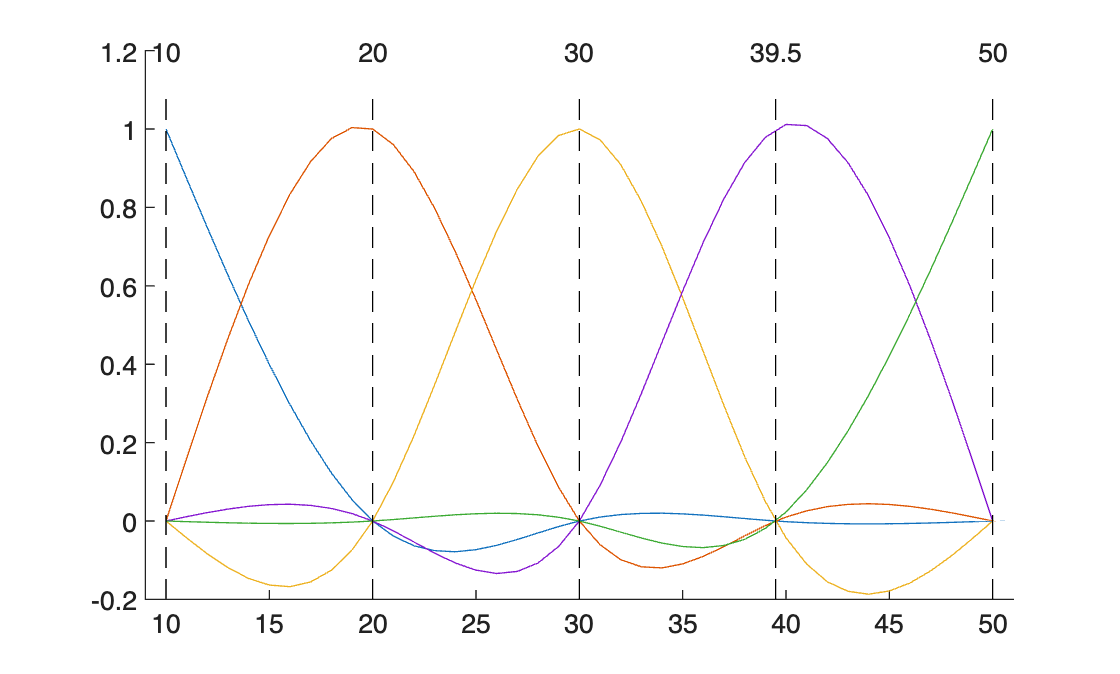

% Create basis functions
knots       = [];
splineType  = 'nsk';
Xpowers     = [];
method      = 'raw';
[basisFunctions, ~, ~, ~, settings] = createBasisFunctions(age, knots, splineType, Xpowers, method);

% Visualize splines
figure;
plot(age, basisFunctions);
box off
hold on
ax = gca;
for ii = 1:length(settings.knots)
    plot([settings.knots(ii) settings.knots(ii)], [ax.YLim(1) 1.1], ...
          'LineStyle', '--', 'LineWidth', 0.5, 'Color', 'k');
    text(settings.knots(ii), ax.YLim(2), num2str(settings.knots(ii)), 'HorizontalAlignment', 'center');
end
xlim([9 ax.XLim(2)+1]);

## Version 2: Create basis functions using custom knot placement

% Create basis functions with custom knots at 25 and 35 years
knots       = [25, 35];
splineType  = 'nsk';
Xpowers     = [];
method      = 'raw';
[basisFunctions, ~, ~, ~, settings] = createBasisFunctions(age, knots, splineType, Xpowers, method);

Creating nsk splines using MATLAB; added knot at: 10
Creating nsk splines using MATLAB; added knot at: 50


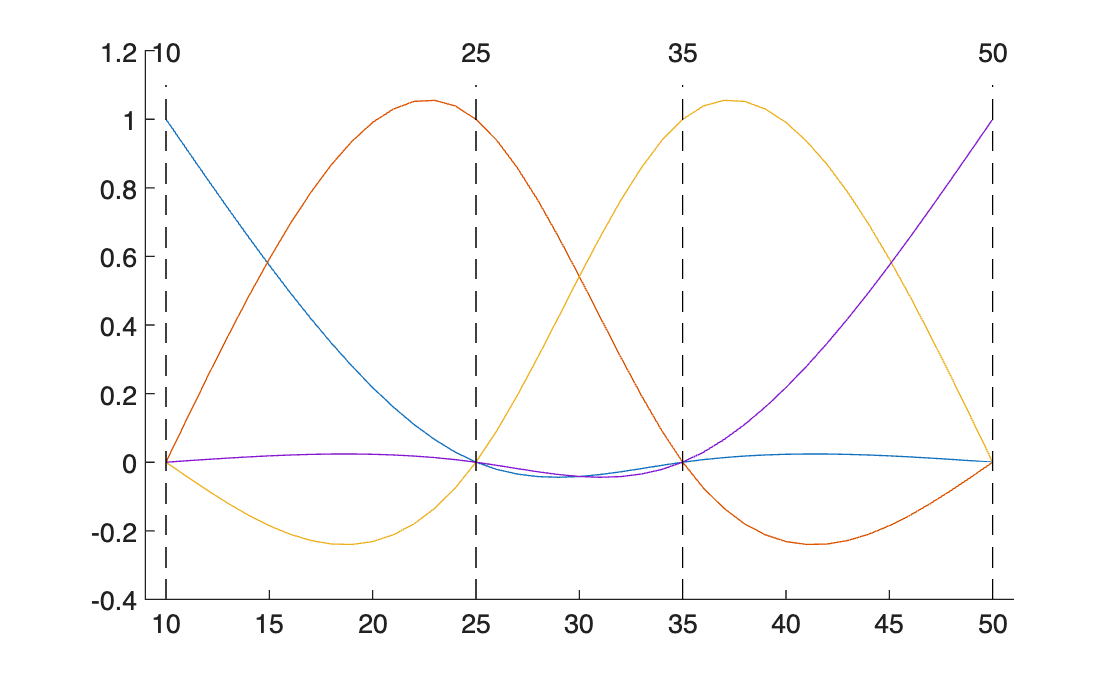


% Visualize splines
figure;
plot(age, basisFunctions);
box off
hold on
ax = gca;
for ii = 1:length(settings.knots)
    plot([settings.knots(ii) settings.knots(ii)], [ax.YLim(1) 1.1], ...
          'LineStyle', '--', 'LineWidth', 0.5, 'Color', 'k');
    text(settings.knots(ii), ax.YLim(2), num2str(settings.knots(ii)), 'HorizontalAlignment', 'center');
end
xlim([9 ax.XLim(2)+1]);

## Version 3: create and modify basis functions using SVD, to be included in another design matrix (to prevent rank deficiency)

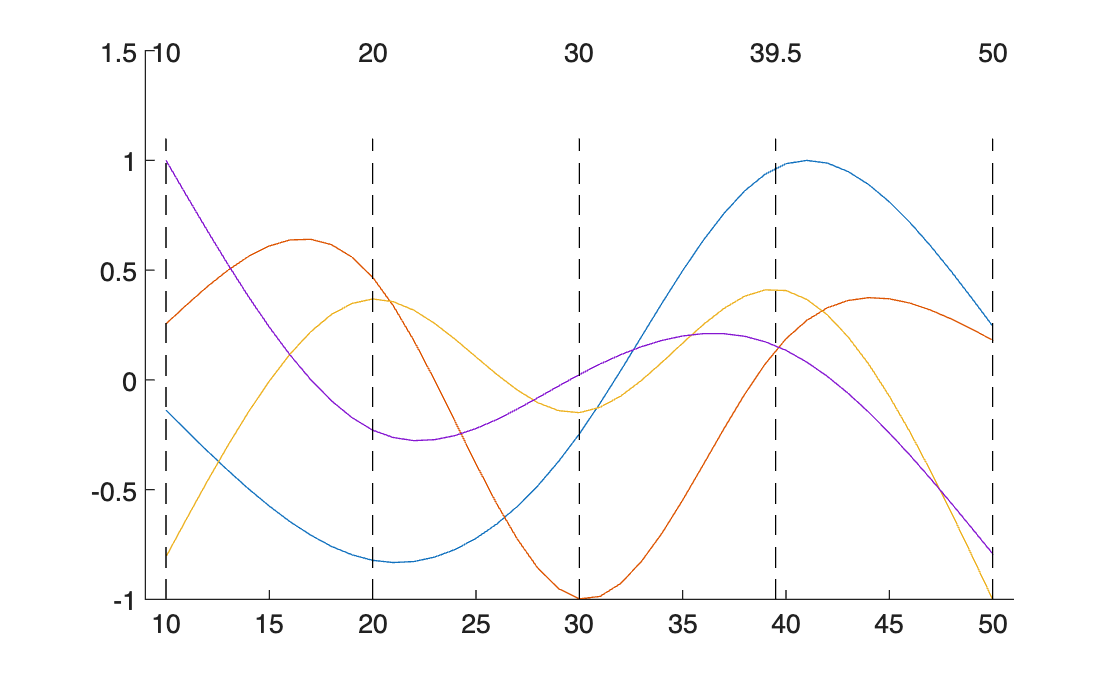

% Create basis functions
knots       = [];
splineType  = 'nsk';
Xpowers     = [];
method      = 'svd';
[basisFunctions, ~, ~, ~, settings] = createBasisFunctions(age, knots, splineType, Xpowers, method);

% Visualize splines
figure;
plot(age, basisFunctions);
box off
hold on
ax = gca;
for ii = 1:length(settings.knots)
    plot([settings.knots(ii) settings.knots(ii)], [ax.YLim(1) 1.1], ...
          'LineStyle', '--', 'LineWidth', 0.5, 'Color', 'k');
    text(settings.knots(ii), ax.YLim(2), num2str(settings.knots(ii)), 'HorizontalAlignment', 'center');
end
xlim([9 ax.XLim(2)+1]);